clear; clc;
sympref('AbbreviateOutput',false);

syms F k_a k_20 FM_3 k_me CL_6tgn k_ma Base k_tr slope gamma

% 6MP dose in mg. 40mg is the median dose
syms ubar
ubar_val = 40;

% Operating point taken at equilibrium of the system when dose is ubar
xbar_4 = (1-slope*FM_3*k_me*F*ubar/(CL_6tgn*k_20))^(1/gamma)*(Base*k_ma/k_tr);
xbar_sym = [F*ubar/k_a;
        F*ubar/k_20;
        FM_3*k_me*F*ubar/(CL_6tgn*k_20);
        xbar_4;
        xbar_4;
        xbar_4;
        xbar_4;
        (1-slope*FM_3*k_me*F*ubar/(CL_6tgn*k_20))^(1/gamma)*Base];

% Median value from patients (Table 1)
% BSA = 0.82;
% F = 0.22;
% k_a = 31.2;
% k_20 = 12.72;
% FM_3 = 0.019;
% k_me = 9.9216;
% CL_6tgn = 0.219*BSA^1.16;
% k_ma = 2.3765;

% Patient-specific parameters (Table 5)
% Base = 2.34;
% k_tr = 0.148;
% slope = 0.242;
% gamma_ = 0.769;

symbols = [F,k_a,k_20,FM_3,k_me,CL_6tgn,k_ma,Base,slope,gamma,ubar];
values = [0.22,31.2,12.72,0.019,9.9216,0.219*0.82^1.16,2.3765,2.34,0.242,0.769,40];

% Initial condition specified in Jost 2020
x0_jost_sym = [0; 0; 0; (Base*k_ma)/k_tr; (Base*k_ma)/k_tr; (Base*k_ma)/k_tr; (Base*k_ma)/k_tr; Base];
x0_jost = double(vpa(subs(x0_jost_sym,[symbols,k_tr],[values,0.148])));

xbar = double(vpa(subs(xbar_sym,[symbols,k_tr],[values,0.148])));

Generate linearization around this equilibrium point:

% Model Dynamics:
A_jost = sym(zeros(8,8));
A_jost(1,1) = -k_a;
A_jost(2,1) = k_a;
A_jost(2,2) = -k_20;
A_jost(3,2) = FM_3*k_me;
A_jost(3,3) = -CL_6tgn;
A_jost(4,3) = -k_tr*xbar_sym(4)*slope*(Base/xbar_sym(8))^gamma;
A_jost(4,4) = k_tr*(1-slope*xbar_sym(3))*(Base/xbar_sym(8))^gamma - k_tr;
A_jost(4,8) = -k_tr*xbar_sym(4)*(1-slope*xbar_sym(3))*Base^gamma*gamma*xbar_sym(8)^(-gamma-1);
A_jost(5,4) = k_tr;
A_jost(5,5) = -k_tr;
A_jost(6,5) = k_tr;
A_jost(6,6) = -k_tr;
A_jost(7,6) = k_tr;
A_jost(7,7) = -k_tr;
A_jost(8,7) = k_tr;
A_jost(8,8) = -k_ma

$$A\_jost = \left(\begin{array}{cccccccc} -k_{a} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ k_{a} & -k_{20} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{FM}}_{3}\,k_{\mathrm{me}} & -{\mathrm{CL}}_{\mathrm{6tgn}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\mathrm{Base}\,k_{\mathrm{ma}}\,\mathrm{slope}\,{\left(1-\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}\right)}^{1/\gamma }\,{\left(\frac{1}{{\left(1-\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}\right)}^{1/\gamma }}\right)}^{\gamma } & -k_{\mathrm{tr}}-k_{\mathrm{tr}}\,\left(\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}-1\right)\,{\left(\frac{1}{{\left(1-\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}\right)}^{1/\gamma }}\right)}^{\gamma } & 0 & 0 & 0 & \frac{\mathrm{Base}\,{\mathrm{Base}}^{\gamma }\,\gamma \,k_{\mathrm{ma}}\,\left(\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}-1\right)\,{\left(1-\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}\right)}^{1/\gamma }}{{\left(\mathrm{Base}\,{\left(1-\frac{F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}}{{\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}}\right)}^{1/\gamma }\right)}^{\gamma +1}}\\ 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{tr}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{tr}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{tr}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{ma}} \end{array}\right)$$

simplify(A_jost,'IgnoreAnalyticConstraints',true)

$$ans = \left(\begin{array}{cccccccc} -k_{a} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ k_{a} & -k_{20} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{FM}}_{3}\,k_{\mathrm{me}} & -{\mathrm{CL}}_{\mathrm{6tgn}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -\mathrm{Base}\,{{\mathrm{CL}}_{\mathrm{6tgn}}}^{1-\frac{1}{\gamma }}\,{k_{20}}^{1-\frac{1}{\gamma }}\,k_{\mathrm{ma}}\,\mathrm{slope}\,{\left({\mathrm{CL}}_{\mathrm{6tgn}}\,k_{20}-F\,{\mathrm{FM}}_{3}\,k_{\mathrm{me}}\,\mathrm{slope}\,\mathrm{ubar}\right)}^{\frac{1}{\gamma }-1} & 0 & 0 & 0 & 0 & -\gamma \,k_{\mathrm{ma}}\\ 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{tr}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{tr}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{tr}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & k_{\mathrm{tr}} & -k_{\mathrm{ma}} \end{array}\right)$$

B_jost = [F; zeros(7,1)];
C_jost = [zeros(1,7) 1];
D_jost = zeros(8,1);

## Rewrite system as LFR:

syms k_tr0
x0 = subs(xbar_sym,k_tr,k_tr0);

A0_sym = sym(zeros(8));
A0_sym(1,1) = -k_a;
A0_sym(2,1) = k_a;
A0_sym(2,2) = -k_20;
A0_sym(3,2) = FM_3*k_me;
A0_sym(3,3) = -CL_6tgn;
A0_sym(4,3) = -k_tr0*x0(4)*slope*(Base/x0(8))^gamma;
A0_sym(4,4) = k_tr0*(1-slope*x0(3))*(Base/x0(8))^gamma - k_tr0; % Should evaluate to zero at the equilibrium point
A0_sym(4,8) = -k_tr0*x0(4)*(1-slope*x0(3))*Base^gamma*gamma*x0(8)^(-gamma-1);
A0_sym(5,4) = k_tr0;
A0_sym(5,5) = -k_tr0;
A0_sym(6,5) = k_tr0;
A0_sym(6,6) = -k_tr0;
A0_sym(7,6) = k_tr0;
A0_sym(7,7) = -k_tr0;
A0_sym(8,7) = k_tr0;
A0_sym(8,8) = -k_ma;
% simplify(A0_sym,'IgnoreAnalyticConstraints',true)
% expand(A0_sym(4,3),'IgnoreAnalyticConstraints',true)

syms W delta

uncertainty = 0.9;
k_tr_ave = 0.148;
k_tr_min = k_tr_ave*(1-uncertainty);
k_tr_max = k_tr_ave*(1+uncertainty);
W_val = 1/k_tr_ave*(k_tr_max - k_tr_min)/2;

Factorize $\Delta$ as $LR$ using row reduction in reverse

L_ = (eye(8)-diag([0 0 0 0 1 1 1],1))*[zeros(4);eye(4)];
R_sym = [zeros(4,3) k_tr0*W*eye(4) zeros(4,1)];
R = double(vpa(subs(R_sym,[W,k_tr0],[W_val,k_tr_ave])));

A1 = L_*R

A1 =          0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0    0.1332   -0.1332         0         0         0
         0         0         0         0    0.1332   -0.1332         0         0
         0         0         0         0         0    0.1332   -0.1332         0
         0         0         0         0         0         0    0.1332         0


### Define system

Create new LFR, with a diagonal parameter block


$$\dot x = A_0 x + B_p L p + B_w w + B_u u$$



$$q = Rx$$



$$p = \Delta q = \delta I_4 q$$



$$z = Cx$$


n = 8;
m = 1;
np = 4;
nq = 4;
nz = 2;
nw = 1;

A0 = double(vpa(subs(A0_sym,[symbols k_tr0],[values k_tr_ave])))

A0 =   -31.2000         0         0         0         0         0         0         0
   31.2000  -12.7200         0         0         0         0         0         0
         0    0.1885   -0.1740         0         0         0         0         0
         0         0   -1.2672         0         0         0         0   -1.8275
         0         0         0    0.1480   -0.1480         0         0         0
         0         0         0         0    0.1480   -0.1480         0         0
         0         0         0         0         0    0.1480   -0.1480         0
         0         0         0         0         0         0    0.1480   -2.3765


Bp = L_;
Bu = double(vpa(subs(B_jost,symbols,values)));
Bw = x0_jost - xbar

Bw =    -0.2821
   -0.6918
   -0.7497
    8.6117
    8.6117
    8.6117
    8.6117
    0.5363


Cq = R;
Cz = [zeros(1,n-1) 0.05; zeros(m,8)]

Cz =          0         0         0         0         0         0         0    0.0500
         0         0         0         0         0         0         0         0


Cy = double(vpa(subs(C_jost,symbols,values)));
Dqp = zeros(nq,np);
Dqw = zeros(nq,nw);
Dqu = zeros(nq,m);
Dzp = zeros(nz,np);
Dzw = zeros(nz,nw);
Dzu = [zeros(1,m); 0.01];

## Quadratically stabilizing state feedback from Scherer & Weiland

Robust stability of CL, Jacobian linearized, state feedback system without considering LFR:

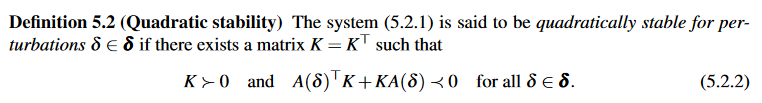

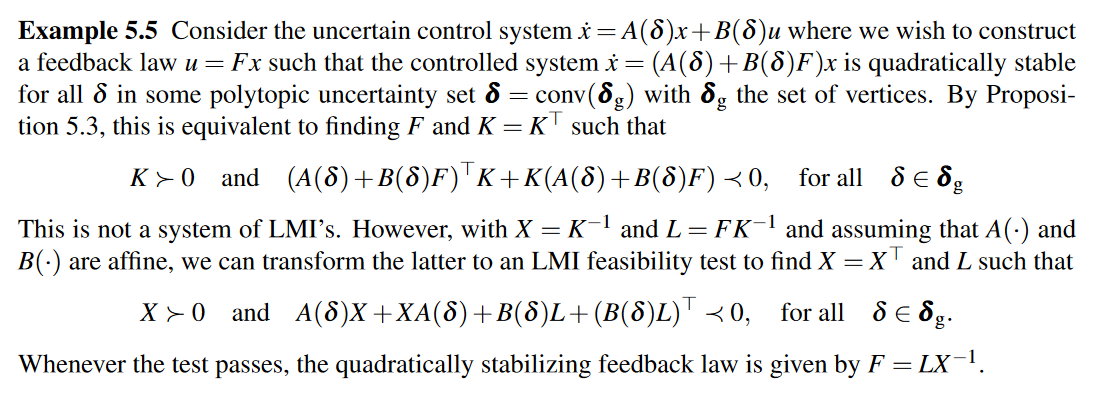

Note: There is a transpose symbol missing in the last LMI. Should be $XA^\top$.

A_min = double(vpa(subs(A_jost,[symbols k_tr],[values k_tr_min])));
A_max = double(vpa(subs(A_jost,[symbols k_tr],[values k_tr_max])));

X = sdpvar(n);
L = sdpvar(m,n,'full');
eps = 1e-5;

constraints = [
    X >= eps*eye(n);
    A_min*X + X*A_min' + Bu*L + L'*Bu' <= -eps*eye(n);
    A_max*X + X*A_max' + Bu*L + L'*Bu' <= -eps*eye(n);
];

cost = 0;
options = sdpsettings('solver','sdpt3','verbose',1);
sol = optimize(constraints,cost,options);


 num. of constraints = 44
 dim. of sdp    var  = 24,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.9e+03|3.6e+02|1.5e+04|-2.400000e-03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.574|0.791|7.9e+02|7.5e+01|6.7e+03|-1.773477e-03  0.000000e+00| 0:0:00| chol  1  1 
 2|0.533|0.820|3.7e+02|1.3e+01|3.7e+03|-1.408624e-03  0.000000e+00| 0:0:01| chol  1  1 
 3|0.653|1.000|1.3e+02|1.0e-03|1.7e+03|-7.816971e-04  0.000000e+00| 0:0:01| chol  1  1 
 4|0.986|1.000|1.8e+00|1.0e-04|2.4e+01|-1.083825e-05  0.000000e+00| 0:0:01| chol  1  1 
 5|0.989|1.000|2.0e-02|1.0e-05|2.6e-01|-1.193749e-07  0.000000e+00| 0:

sol.info

ans = 'Successfully solved (SDPT3)'

K_quad = value(L)*inv(value(X))

K_quad =   177.7663 -317.3648 -786.9278  256.0281   37.9032    8.1326  -28.0986 -202.6611


Simulate response using the controller found above

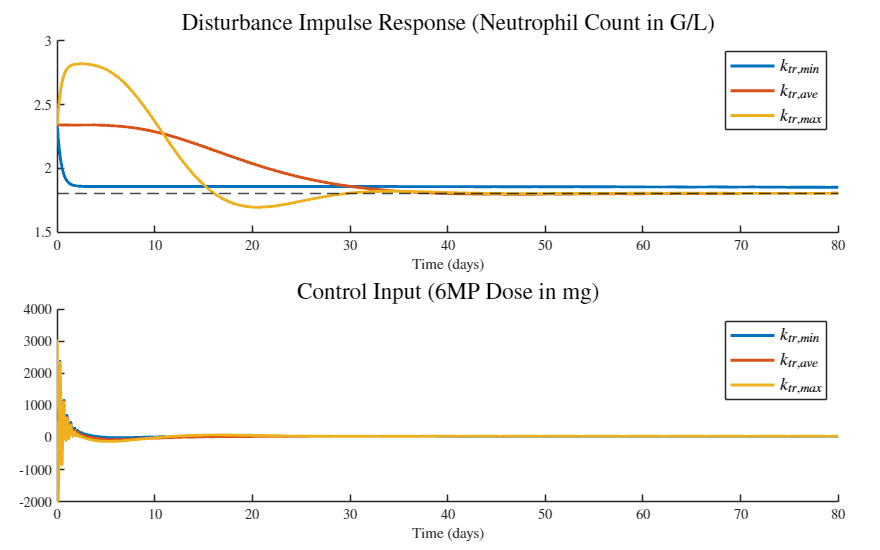

sys_min = ss(A_min+Bu*K_quad,zeros(n,nw),eye(n),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});
sys_max = ss(A_max+Bu*K_quad,zeros(n,nw),eye(n),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});
sys_nom = ss(A0+Bu*K_quad,zeros(n,nw),eye(8),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});

t = 0:0.1:80;
u = zeros(length(t),nw);
x_min_quad = lsim(sys_min,u,t,x0_jost-xbar);
x_max_quad = lsim(sys_max,u,t,x0_jost-xbar);
x_nom_quad = lsim(sys_nom,u,t,x0_jost-xbar);
u_min_quad = K_quad*x_min_quad'+repmat(ubar_val,1,length(t));
u_nom_quad = K_quad*x_nom_quad'+repmat(ubar_val,1,length(t));
u_max_quad = K_quad*x_max_quad'+repmat(ubar_val,1,length(t));

f = figure('Position',[0 0 800 500]);
tiledlayout(2,1,"TileSpacing","tight","Padding","compact");

nexttile;
hold on
plot(t,x_min_quad(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
plot(t,x_nom_quad(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
plot(t,x_max_quad(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
yline(xbar(8),'k--')
title("Disturbance Impulse Response (Neutrophil Count in G/L)",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
legend('$k_{tr,min}$','$k_{tr,ave}$','$k_{tr,max}$','Interpreter','latex','fontsize',12)
set(gca,'TickLabelInterpreter','latex')

nexttile;
hold on
plot(t,u_min_quad,'linewidth',2)
plot(t,u_nom_quad,'linewidth',2)
plot(t,u_max_quad,'linewidth',2)
title("Control Input (6MP Dose in mg)",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
legend('$k_{tr,min}$','$k_{tr,ave}$','$k_{tr,max}$','Interpreter','latex','fontsize',12)
set(gca,'TickLabelInterpreter','latex')


% set(f,'Visible','on')
% exportgraphics(f,'QuadraticStability.png','Resolution',300)

## Robust H2 state feedback synthesis

Special case of this theorem:

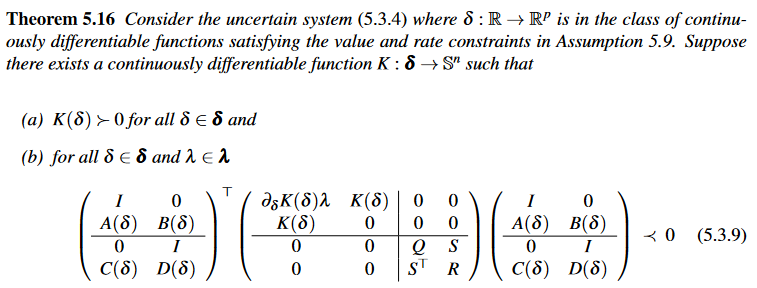

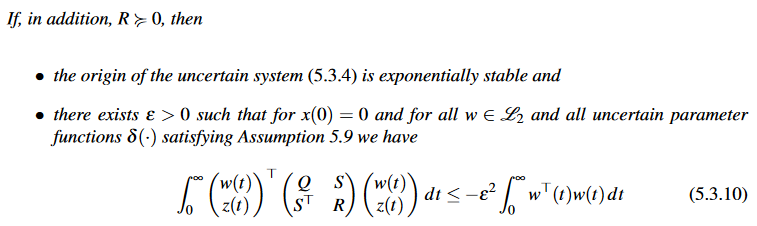

Justification for this is that since $A(\delta)$ is affine and delta lives in a convex set, the function $F(\delta)$ defining the LHS of the LMI is a convex function.

Proposition 1.14 of Scherer and Weiland then says that we can show negative definiteness of $F(\delta)$ for all $\delta \in \mathbf\delta_g$ , the convex hull of the uncertain parameter set.

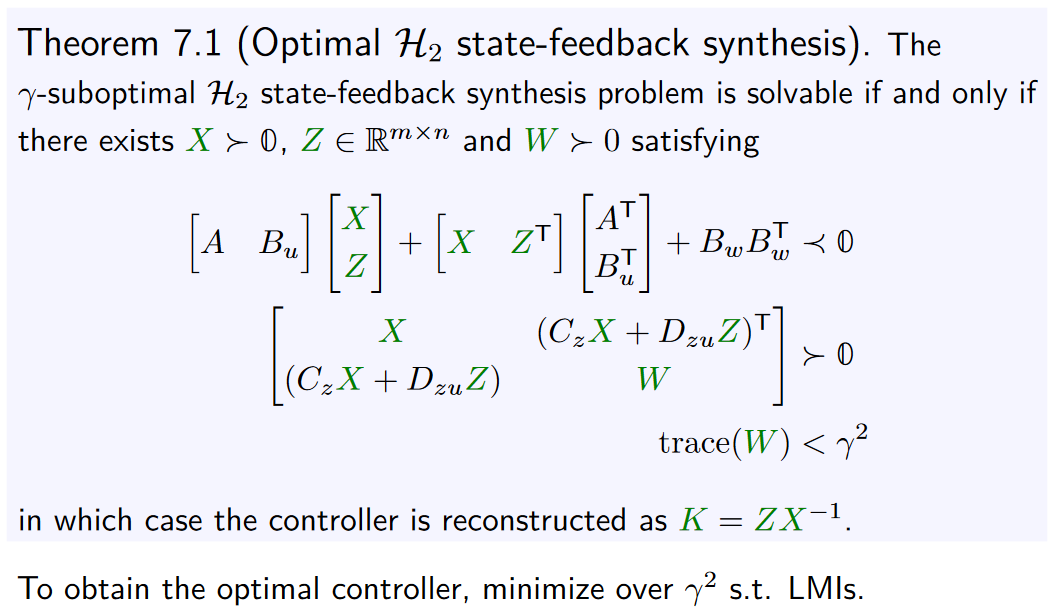

A_min = double(vpa(subs(A_jost,[symbols k_tr],[values k_tr_min])));
A_max = double(vpa(subs(A_jost,[symbols k_tr],[values k_tr_max])));

% eig(A_max)
% eig(A_min)

X = sdpvar(n,n);
Z = sdpvar(m,n,'full');
W = sdpvar(nz,nz);
small = 1e-5;
Constraints = [
    X >= small*eye(n);
    [A_min,Bu]*[X;Z] + ([A_min,Bu]*[X;Z])' + Bw*Bw' <= -small*eye(n);
    [A_max,Bu]*[X;Z] + ([A_max,Bu]*[X;Z])' + Bw*Bw' <= -small*eye(n);
    [X,(Cz*X+Dzu*Z)';(Cz*X+Dzu*Z),W] >= small*eye(n+nz);
];
Cost = trace(W);
options = sdpsettings('solver','sdpt3','verbose',1);
sol = optimize(Constraints,Cost,options);


 num. of constraints = 47
 dim. of sdp    var  = 34,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.2e+03|3.3e+00|7.9e+04|-9.537617e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.208|0.492|9.8e+02|1.7e+00|6.3e+04|-1.455351e+04 -1.362506e+02| 0:0:00| chol  1  1 
 2|0.085|0.123|8.9e+02|1.5e+00|6.4e+04|-5.591258e+04 -2.003131e+02| 0:0:00| chol  1  1 
 3|0.010|0.012|8.8e+02|1.5e+00|7.0e+04|-2.256958e+05 -2.176214e+02| 0:0:00| chol  1  1 
 4|0.011|0.012|8.7e+02|1.4e+00|9.6e+04|-2.159519e+05 -2.076124e+02| 0:0:00| chol  1  1 
 5|0.028|0.041|8.5e+02|1.4e+00|1.4e+05|-2.573572e+05 -2.492381e+02| 0:

sol.info

ans = 'Successfully solved (SDPT3)'

K_H2 = value(Z)*inv(value(X))

K_H2 =    -0.1360   -0.1361   -9.1936    1.3679    0.0800   -0.2738   -0.7393   -1.0522


sqrt(value(Cost))

ans = 3.6427

Simulate response using the controller found above

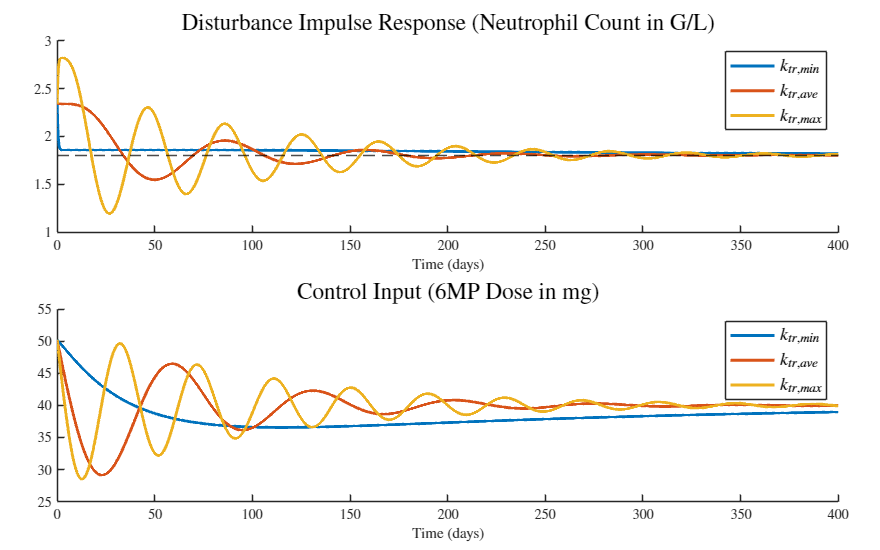

sys_min = ss(A_min+Bu*K_H2,zeros(n,nw),eye(n),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});
sys_max = ss(A_max+Bu*K_H2,zeros(n,nw),eye(n),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});
sys_nom = ss(A0+Bu*K_H2,zeros(n,nw),eye(8),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});

t = 0:0.1:400;
u = zeros(length(t),nw);
x_min_H2 = lsim(sys_min,u,t,x0_jost-xbar);
x_max_H2 = lsim(sys_max,u,t,x0_jost-xbar);
x_nom_H2 = lsim(sys_nom,u,t,x0_jost-xbar);
u_min_H2 = K_H2*x_min_H2'+repmat(ubar_val,1,length(t));
u_nom_H2 = K_H2*x_nom_H2'+repmat(ubar_val,1,length(t));
u_max_H2 = K_H2*x_max_H2'+repmat(ubar_val,1,length(t));


f = figure('Position',[0 0 800 500]);
tiledlayout(2,1,"TileSpacing","tight","Padding","compact");

nexttile;
hold on
plot(t,x_min_H2(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
plot(t,x_nom_H2(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
plot(t,x_max_H2(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
yline(xbar(8),'k--')
title("Disturbance Impulse Response (Neutrophil Count in G/L)",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
legend('$k_{tr,min}$','$k_{tr,ave}$','$k_{tr,max}$','Interpreter','latex','fontsize',12)
set(gca,'TickLabelInterpreter','latex')

nexttile;
hold on
plot(t,u_min_H2,'linewidth',2)
plot(t,u_nom_H2,'linewidth',2)
plot(t,u_max_H2,'linewidth',2)
title("Control Input (6MP Dose in mg)",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
legend('$k_{tr,min}$','$k_{tr,ave}$','$k_{tr,max}$','Interpreter','latex','fontsize',12)
set(gca,'TickLabelInterpreter','latex')


% set(f,'Visible','on')
% exportgraphics(f,'H2_synthesis.png','Resolution',300)

## Robust $H_\infty$ state feedback synthesis

Justification for this is that since $A(\delta)$ is affine and delta lives in a convex set, the function $F(\delta)$ defining the LHS of the LMI is a convex function.

Does this make sense for the problem setup?

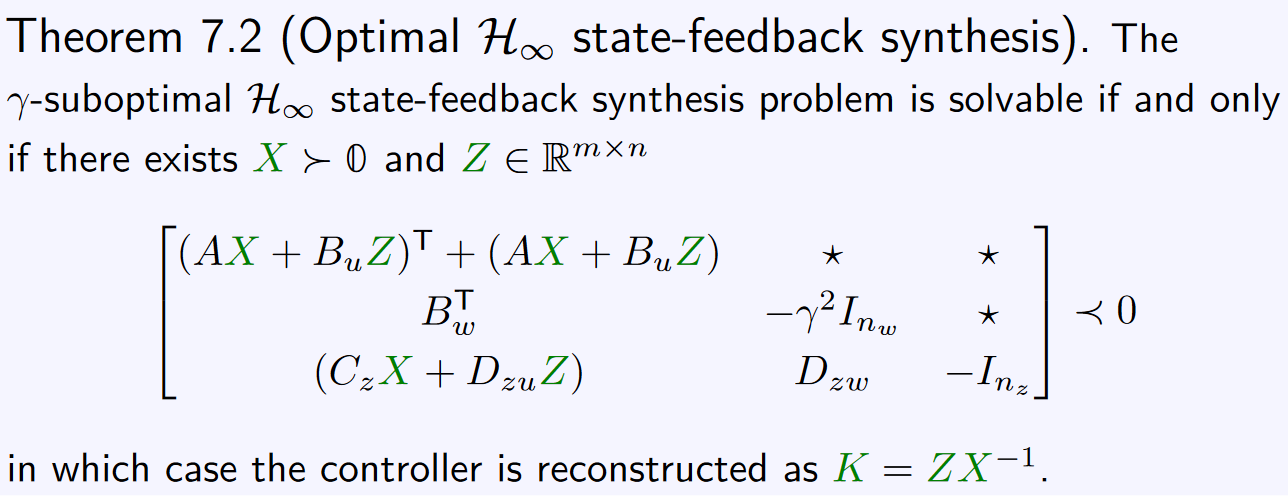

A_min = double(vpa(subs(A_jost,[symbols k_tr],[values k_tr_min])));
A_max = double(vpa(subs(A_jost,[symbols k_tr],[values k_tr_max])));
% eig(A_min)
% eig(A_max)

X = sdpvar(n,n);
Z = sdpvar(m,n,'full');
gamma_sq = sdpvar;
small = 1e-4;

M1 = [
    (A_min*X+Bu*Z)' + A_min*X+Bu*Z, Bw, (Cz*X+Dzu*Z)';
    Bw', -gamma_sq*eye(nw), Dzw';
    (Cz*X+Dzu*Z), Dzw, -eye(nz);
];

M2 = [
    (A_max*X+Bu*Z)' + A_max*X+Bu*Z, Bw, (Cz*X+Dzu*Z)';
    Bw', -gamma_sq*eye(nw), Dzw';
    (Cz*X+Dzu*Z), Dzw, -eye(nz);
];

Constraints = [
    X >= small*eye(n);
    
    M1 <= -eps*eye(n+nw+nz);
    M2 <= -eps*eye(n+nw+nz);
];
Cost = gamma_sq;
options = sdpsettings('solver','sdpt3','verbose',1);
sol = optimize(Constraints,Cost,options);


 num. of constraints = 45
 dim. of sdp    var  = 30,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.0e+03|1.2e+01|2.3e+04| 4.398696e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.625|0.834|3.8e+02|2.0e+00|7.7e+03|-3.486177e+01 -8.802522e+01| 0:0:00| chol  1  1 
 2|0.673|0.831|1.3e+02|3.3e-01|2.8e+03|-4.260785e+01 -1.113575e+02| 0:0:00| chol  1  1 
 3|0.587|0.634|5.2e+01|1.2e-01|1.3e+03|-1.447482e+02 -1.252378e+02| 0:0:00| chol  1  1 
 4|0.385|0.450|3.2e+01|6.7e-02|1.0e+03|-1.607027e+02 -1.369832e+02| 0:0:00| chol  1  1 
 5|0.379|0.541|2.0e+01|3.1e-02|8.3e+02|-1.708929e+02 -1.610125e+02| 0:

sol.info

ans = 'Successfully solved (SDPT3)'

K_Hinf = value(Z)*inv(value(X))

K_Hinf = 1.0e+05 *

   -0.0497   -0.0495   -3.2831   -0.0125    0.0323   -0.0011   -0.0314   -0.0145


sqrt(value(Cost))

ans = 12.4548

Simulate response using the controller found above

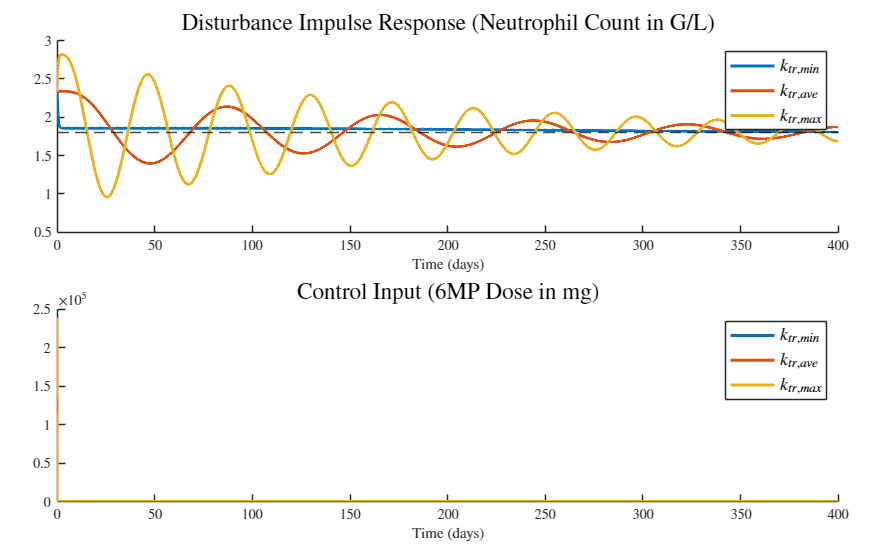

sys_min = ss(A_min+Bu*K_Hinf,zeros(n,nw),eye(n),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});
sys_max = ss(A_max+Bu*K_Hinf,zeros(n,nw),eye(n),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});
sys_nom = ss(A0+Bu*K_Hinf,zeros(n,nw),eye(8),zeros(n,nw),'TimeUnit','Days','OutputName',{'x_1','x_2','x_3','x_4','x_5','x_6','x_7','x_8'});

t = 0:0.1:400;
u = zeros(length(t),nw);
x_min_Hinf = lsim(sys_min,u,t,x0_jost-xbar);
x_max_Hinf = lsim(sys_max,u,t,x0_jost-xbar);
x_nom_Hinf = lsim(sys_nom,u,t,x0_jost-xbar);
u_min_Hinf = K_Hinf*x_min_Hinf'+repmat(ubar_val,1,length(t));
u_nom_Hinf = K_Hinf*x_nom_Hinf'+repmat(ubar_val,1,length(t));
u_max_Hinf = K_Hinf*x_max_Hinf'+repmat(ubar_val,1,length(t));

f = figure('Position',[0 0 800 500]);
tiledlayout(2,1,"TileSpacing","tight","Padding","compact");

nexttile;
hold on
plot(t,x_min_Hinf(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
plot(t,x_nom_Hinf(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
plot(t,x_max_Hinf(:,8) + repmat(xbar(8),length(t),1),'linewidth',2)
yline(xbar(8),'k--')
title("Disturbance Impulse Response (Neutrophil Count in G/L)",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
legend('$k_{tr,min}$','$k_{tr,ave}$','$k_{tr,max}$','Interpreter','latex','fontsize',12)
set(gca,'TickLabelInterpreter','latex')

% set(f,'Visible','on')
% exportgraphics(f,'HW3Q4ii_plots.png')

nexttile;
hold on
plot(t,u_min_Hinf','linewidth',2)
plot(t,u_nom_Hinf','linewidth',2)
plot(t,u_max_Hinf','linewidth',2)
title("Control Input (6MP Dose in mg)",'Interpreter','latex','FontSize',16)
xlabel('Time (days)','Interpreter','latex')
legend('$k_{tr,min}$','$k_{tr,ave}$','$k_{tr,max}$','Interpreter','latex','fontsize',12)
set(gca,'TickLabelInterpreter','latex')


% set(f,'Visible','on')
% exportgraphics(f,'Hinf_synthesis.png','Resolution',300)

## Parameter Dependent Controllers

From Corentin Briat, "Linear Parameter-Varying and Time-Delay Systems Analysis, Observation, Filtering & Control"

**Note: **This method was infeasible so it was not used

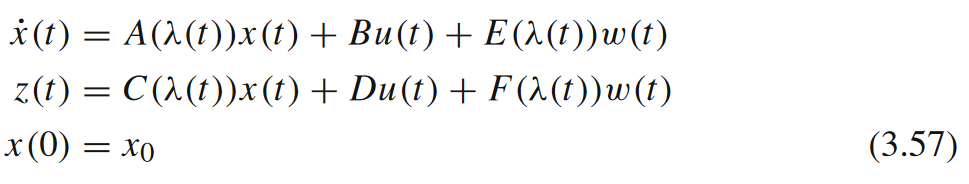

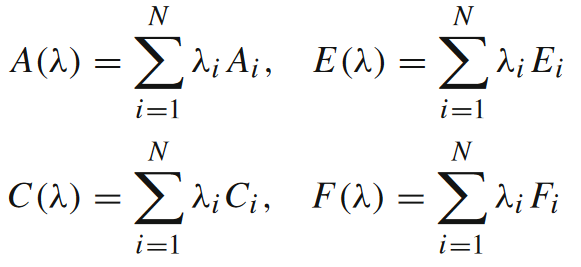

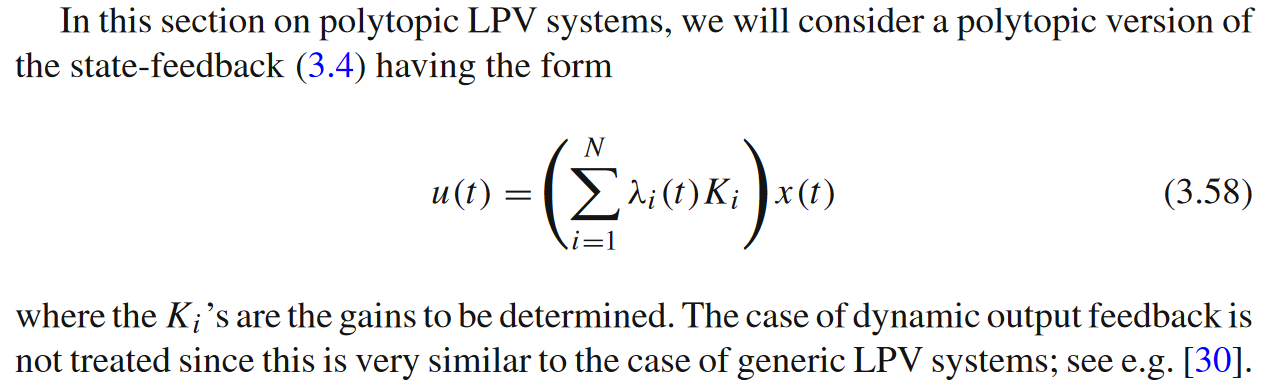

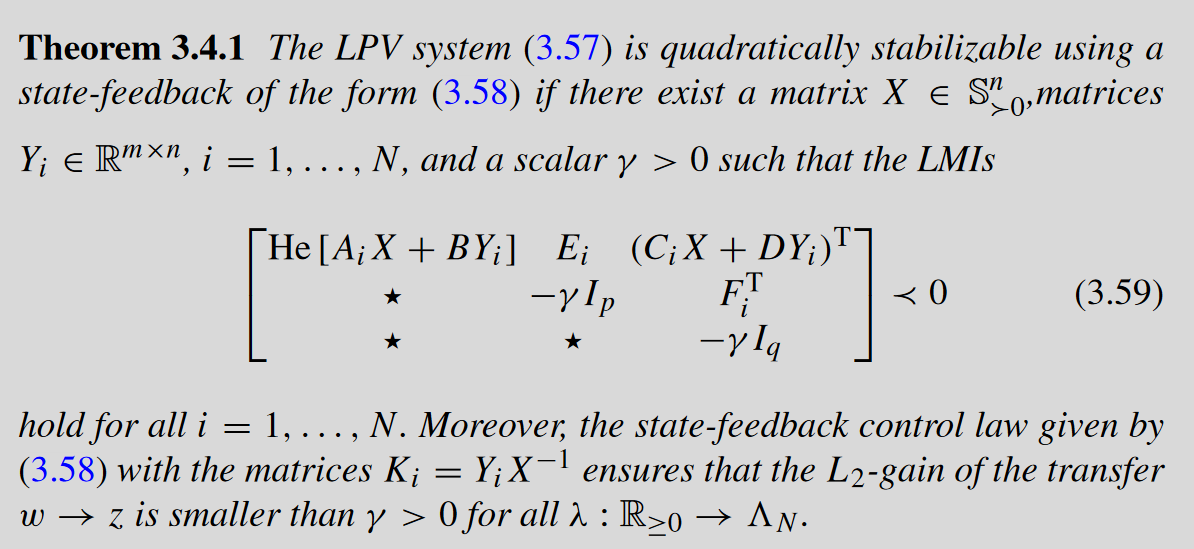

X = sdpvar(n,n);
Y0 = sdpvar(m,n,'full');
Y1 = sdpvar(m,n,'full');
gamma = sdpvar;
eps = 1e-6;

M0 = [
    (A0*X+Bu*Y0)' + A0*X+Bu*Y0, Bw, (Cz*X+Dzu*Y0)';
    Bw', -gamma*eye(nw), Dzw';
    (Cz*X+Dzu*Y0), Dzw, -gamma*eye(nz);
];

M1 = [
    (A1*X+Bu*Y1)' + A1*X+Bu*Y1, Bw, (Cz*X+Dzu*Y1)';
    Bw', -gamma*eye(nw), Dzw';
    (Cz*X+Dzu*Y1), Dzw, -gamma*eye(nz);
];

Constraints = [
    X >= eps*eye(n);
    
    M0 <= -eps*eye(n+nw+nz);
    M1 <= -eps*eye(n+nw+nz);
];
Cost = gamma;
options = sdpsettings('solver','sdpt3','verbose',1);
sol = optimize(Constraints,Cost,options);


 num. of constraints = 53
 dim. of sdp    var  = 30,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.2e+02|8.7e+00|1.5e+04|-3.700000e-04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.614|0.794|2.0e+02|1.8e+00|5.9e+03|-1.390274e+02 -5.416682e+01| 0:0:00| chol  1  1 
 2|0.570|0.419|8.6e+01|1.1e+00|3.1e+03|-8.501926e+02 -7.708951e+01| 0:0:00| chol  1  1 
 3|0.306|0.473|5.9e+01|5.5e-01|2.6e+03|-1.211373e+03 -1.590950e+02| 0:0:00| chol  1  1 
 4|0.310|0.313|4.1e+01|3.8e-01|2.4e+03|-1.394051e+03 -2.308842e+02| 0:0:00| chol  1  1 
 5|0.157|0.355|3.5e+01|2.5e-01|2.4e+03|-1.640372e+03 -3.382290e+02| 0:

sol.info

ans = 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (SDPT3)'

sqrt(value(Cost))

ans = 1.0241e+04